# Savitzky-Golay Filtering

A program which is developed based on Savitzky-Golay approach for smoothing rate-normalized pressure (RNP) data.

Author: Munthe, Felix A.

Created on Monday, 30 October 2023

## Import Data

### True RNP Data

clear; clc; clf;
opts = delimitedTextImportOptions("NumVariables", 2);

% Specify range and delimiter
opts.DataLines = [2, Inf];
opts.Delimiter = "\t";

% Specify column names and types
opts.VariableNames = ["t", "RNP"];
opts.VariableTypes = ["double", "double"];

% Specify file level properties
opts.ExtraColumnsRule = "ignore";
opts.EmptyLineRule = "read";

% Import the data
true_RNP = readtable("C:\Users\ASUS\Documents\Kuliah\2. Master's Texas A&M University\Publications\Conference Paper\Smoothing Paper\Smoothing Simulator\true_RNP.txt", opts)

true_RNP = 1150×2 table
       t          RNP    
    _______    __________

       0.25    1.3616e+06
    0.33041    1.9565e+06
     0.4862    2.6089e+06
    0.79777    3.4782e+06
     1.4209    4.6953e+06
     2.6672    6.4232e+06
     5.0773    8.8236e+06
     9.8974    1.2258e+07
     19.198    1.7054e+07
     35.645    2.3347e+07
      66.06    3.1893e+07
     124.99    4.3906e+07
     188.99    5.4925e+07
     252.99    6.4572e+07
     316.99    7.3193e+07
     380.99     8.103e+07


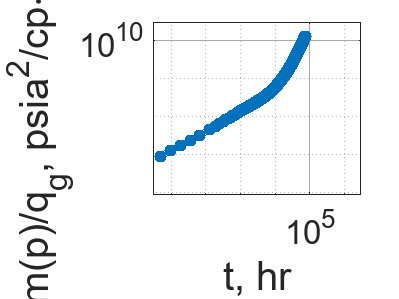


% Plot
loglog(true_RNP.t, true_RNP.RNP, ".", "MarkerSize", 25,"Color", "#0072BD");
% title("True RNP Data", "FontSize", 24);
set(gca, "FontSize", 20);
xlabel("t, hr", "FontSize", 24);
ylabel("\Deltam(p)/q_{g}, psia^{2}/cp\cdotd/Mscf", "FontSize", 24);
xlim([3 3000000]);
ylim([900000 30000000000]);
set(gca, "GridAlpha", 0.4);
set(gca, "MinorGridAlpha", 0.3);
grid on;
hold off;

### Noisy RNP Data Set 192

opts = delimitedTextImportOptions("NumVariables", 2);

% Specify range and delimiter
opts.DataLines = [2, Inf];
opts.Delimiter = "\t";

% Specify column names and types
opts.VariableNames = ["t", "RNP"];
opts.VariableTypes = ["double", "double"];

% Specify file level properties
opts.ExtraColumnsRule = "ignore";
opts.EmptyLineRule = "read";

% Import the data
noisy_RNP_192 = readtable("C:\Users\ASUS\Documents\Kuliah\2. Master's Texas A&M University\Publications\Conference Paper\Smoothing Paper\Smoothing Simulator\Noisy RNP Model\All\50%\noisy_data_2.txt", opts)

noisy_RNP_192 = 1150×2 table
       t          RNP    
    _______    __________

       0.25    5.0109e+07
    0.33041    1.6026e+08
     0.4862    1.2641e+08
    0.79777    3.4782e+06
     1.4209    7.8606e+07
     2.6672    1.7814e+08
     5.0773    8.8236e+06
     9.8974    1.2258e+07
     19.198    2.1649e+08
     35.645    2.3347e+07
      66.06    3.1893e+07
     124.99    4.3906e+07
     188.99    5.4925e+07
     252.99    6.4572e+07
     316.99    7.3193e+07
     380.99    6.5513e+07


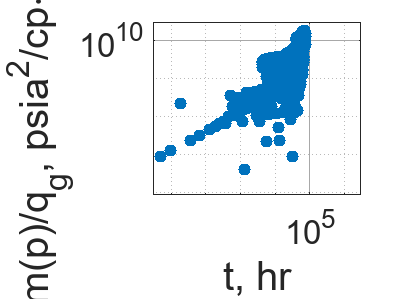


% Plot
loglog(noisy_RNP_192.t, noisy_RNP_192.RNP, ".", "MarkerSize", 25,"Color", "#0072BD");
% title("Noisy RNP Data Set 192", "FontSize", 24);
set(gca, "FontSize", 20);
xlabel("t, hr", "FontSize", 24);
ylabel("\Deltam(p)/q_{g}, psia^{2}/cp\cdotd/Mscf", "FontSize", 24);
xlim([3 3000000]);
ylim([900000 30000000000]);
set(gca, "GridAlpha", 0.4);
set(gca, "MinorGridAlpha", 0.3);
grid on;
hold off;

## Smoothing

### Noisy RNP Data 192

logRNP_192 = log(noisy_RNP_192.RNP);

#### Window: 3

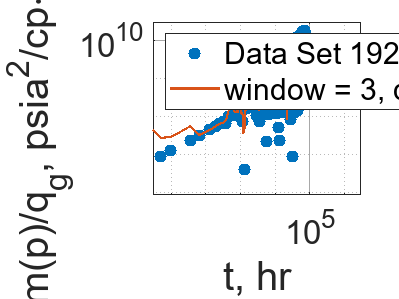

% Plot
loglog(noisy_RNP_192.t, noisy_RNP_192.RNP, ".", "MarkerSize", 25,"Color", "#0072BD", "DisplayName", "Data Set 192");
% title("Noisy RNP Data Set 192", "FontSize", 24);
set(gca, "FontSize", 20);
xlabel("t, hr", "FontSize", 24);
ylabel("\Deltam(p)/q_{g}, psia^{2}/cp\cdotd/Mscf", "FontSize", 24);
xlim([3 3000000]);
ylim([900000 30000000000]);
set(gca, "GridAlpha", 0.4);
set(gca, "MinorGridAlpha", 0.3);
grid on;
hold on;

% Degree = 1
smoothedLogRNP_192_31 = smooth(logRNP_192, 3, "sgolay", 1);
smoothedRNP_192_31 = exp(smoothedLogRNP_192_31);
residual_192_31 = (true_RNP.RNP - smoothedRNP_192_31) ./ (0.3413 .* true_RNP.RNP);
sse_192_31 = sum(residual_192_31 .^ 2);
loglog(noisy_RNP_192.t, smoothedRNP_192_31, "-", "LineWidth", 1.3, "DisplayName", "window = 3, degree = 1");
legend("Location", "northwest");
hold off;

### Window: 5

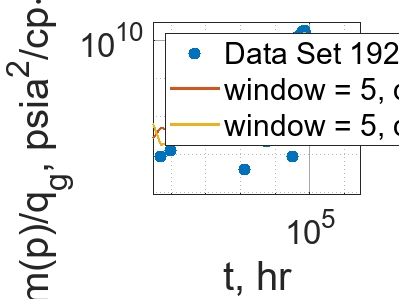

% Plot
loglog(noisy_RNP_192.t, noisy_RNP_192.RNP, ".", "MarkerSize", 25,"Color", "#0072BD", "DisplayName", "Data Set 192");
% title("Noisy RNP Data Set 192", "FontSize", 24);
set(gca, "FontSize", 20);
xlabel("t, hr", "FontSize", 24);
ylabel("\Deltam(p)/q_{g}, psia^{2}/cp\cdotd/Mscf", "FontSize", 24);
xlim([3 3000000]);
ylim([900000 30000000000]);
set(gca, "GridAlpha", 0.4);
set(gca, "MinorGridAlpha", 0.3);
grid on;
hold on;

% Degree = 1
smoothedLogRNP_192_51 = smooth(logRNP_192, 5, "sgolay", 1);
smoothedRNP_192_51 = exp(smoothedLogRNP_192_51);
residual_192_51 = (true_RNP.RNP - smoothedRNP_192_51) ./ (0.3413 .* true_RNP.RNP);
sse_192_51 = sum(residual_192_51 .^ 2);
loglog(noisy_RNP_192.t, smoothedRNP_192_51, "-", "LineWidth", 1.3, "DisplayName", "window = 5, degree = 1");
hold on;

% Degree = 2
smoothedLogRNP_192_52 = smooth(logRNP_192, 5, "sgolay", 2);
smoothedRNP_192_52 = exp(smoothedLogRNP_192_52);
residual_192_52 = (true_RNP.RNP - smoothedRNP_192_52) ./ (0.3413 .* true_RNP.RNP);
sse_192_52 = sum(residual_192_52 .^ 2);
loglog(noisy_RNP_192.t, smoothedRNP_192_52, "-", "LineWidth", 1.3, "DisplayName", "window = 5, degree = 2");
legend("Location", "northwest");
hold off;

#### Window: 7

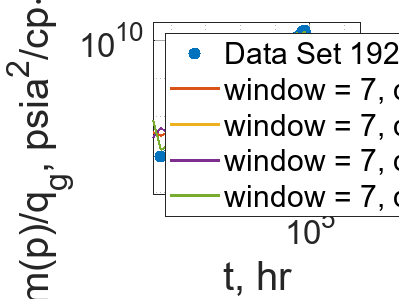

% Plot
loglog(noisy_RNP_192.t, noisy_RNP_192.RNP, ".", "MarkerSize", 25,"Color", "#0072BD", "DisplayName", "Data Set 192");
% title("Noisy RNP Data Set 192", "FontSize", 24);
set(gca, "FontSize", 20);
xlabel("t, hr", "FontSize", 24);
ylabel("\Deltam(p)/q_{g}, psia^{2}/cp\cdotd/Mscf", "FontSize", 24);
xlim([3 3000000]);
ylim([900000 30000000000]);
set(gca, "GridAlpha", 0.4);
set(gca, "MinorGridAlpha", 0.3);
grid on;
hold on;

% Degree = 1
smoothedLogRNP_192_71 = smooth(logRNP_192, 7, "sgolay", 1);
smoothedRNP_192_71 = exp(smoothedLogRNP_192_71);
residual_192_71 = (true_RNP.RNP - smoothedRNP_192_71) ./ (0.3413 .* true_RNP.RNP);
sse_192_71 = sum(residual_192_71 .^ 2);
loglog(noisy_RNP_192.t, smoothedRNP_192_71, "-", "LineWidth", 1.3, "DisplayName", "window = 7, degree = 1");
hold on;

% Degree = 2
smoothedLogRNP_192_72 = smooth(logRNP_192, 7, "sgolay", 2);
smoothedRNP_192_72 = exp(smoothedLogRNP_192_72);
residual_192_72 = (true_RNP.RNP - smoothedRNP_192_72) ./ (0.3413 .* true_RNP.RNP);
sse_192_72 = sum(residual_192_72 .^ 2);
loglog(noisy_RNP_192.t, smoothedRNP_192_72, "-", "LineWidth", 1.3, "DisplayName", "window = 7, degree = 2");
hold on;

% Degree = 3
smoothedLogRNP_192_73 = smooth(logRNP_192, 7, "sgolay", 3);
smoothedRNP_192_73 = exp(smoothedLogRNP_192_73);
residual_192_73 = (true_RNP.RNP - smoothedRNP_192_73) ./ (0.3413 .* true_RNP.RNP);
sse_192_73 = sum(residual_192_73 .^ 2);
loglog(noisy_RNP_192.t, smoothedRNP_192_73, "-", "LineWidth", 1.3, "DisplayName", "window = 7, degree = 3");
hold on;

% Degree = 4
smoothedLogRNP_192_74 = smooth(logRNP_192, 7, "sgolay", 4);
smoothedRNP_192_74 = exp(smoothedLogRNP_192_74);
residual_192_74 = (true_RNP.RNP - smoothedRNP_192_74) ./ (0.3413 .* true_RNP.RNP);
sse_192_74 = sum(residual_192_74 .^ 2);
loglog(noisy_RNP_192.t, smoothedRNP_192_74, "-", "LineWidth", 1.3, "DisplayName", "window = 7, degree = 4");
legend("Location", "northwest");
hold off;

#### Window: 9

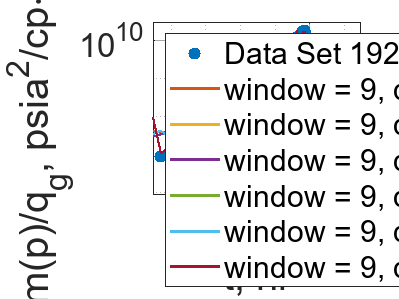

% Plot
loglog(noisy_RNP_192.t, noisy_RNP_192.RNP, ".", "MarkerSize", 25,"Color", "#0072BD", "DisplayName", "Data Set 192");
% title("Noisy RNP Data Set 192", "FontSize", 24);
set(gca, "FontSize", 20);
xlabel("t, hr", "FontSize", 24);
ylabel("\Deltam(p)/q_{g}, psia^{2}/cp\cdotd/Mscf", "FontSize", 24);
xlim([3 3000000]);
ylim([900000 30000000000]);
set(gca, "GridAlpha", 0.4);
set(gca, "MinorGridAlpha", 0.3);
grid on;
hold on;

% Degree = 1
smoothedLogRNP_192_91 = smooth(logRNP_192, 9, "sgolay", 1);
smoothedRNP_192_91 = exp(smoothedLogRNP_192_91);
residual_192_91 = (true_RNP.RNP - smoothedRNP_192_91) ./ (0.3413 .* true_RNP.RNP);
sse_192_91 = sum(residual_192_91 .^ 2);
loglog(noisy_RNP_192.t, smoothedRNP_192_91, "-", "LineWidth", 1.3, "DisplayName", "window = 9, degree = 1");
hold on;

% Degree = 2
smoothedLogRNP_192_92 = smooth(logRNP_192, 9, "sgolay", 2);
smoothedRNP_192_92 = exp(smoothedLogRNP_192_92);
residual_192_92 = (true_RNP.RNP - smoothedRNP_192_92) ./ (0.3413 .* true_RNP.RNP);
sse_192_92 = sum(residual_192_92 .^ 2);
loglog(noisy_RNP_192.t, smoothedRNP_192_92, "-", "LineWidth", 1.3, "DisplayName", "window = 9, degree = 2");
hold on;

% Degree = 3
smoothedLogRNP_192_93 = smooth(logRNP_192, 9, "sgolay", 3);
smoothedRNP_192_93 = exp(smoothedLogRNP_192_93);
residual_192_93 = (true_RNP.RNP - smoothedRNP_192_93) ./ (0.3413 .* true_RNP.RNP);
sse_192_93 = sum(residual_192_93 .^ 2);
loglog(noisy_RNP_192.t, smoothedRNP_192_93, "-", "LineWidth", 1.3, "DisplayName", "window = 9, degree = 3");
hold on;

% Degree = 4
smoothedLogRNP_192_94 = smooth(logRNP_192, 9, "sgolay", 4);
smoothedRNP_192_94 = exp(smoothedLogRNP_192_94);
residual_192_94 = (true_RNP.RNP - smoothedRNP_192_94) ./ (0.3413 .* true_RNP.RNP);
sse_192_94 = sum(residual_192_94 .^ 2);
loglog(noisy_RNP_192.t, smoothedRNP_192_94, "-", "LineWidth", 1.3, "DisplayName", "window = 9, degree = 4");
hold on;

% Degree = 5
smoothedLogRNP_192_95 = smooth(logRNP_192, 9, "sgolay", 5);
smoothedRNP_192_95 = exp(smoothedLogRNP_192_95);
residual_192_95 = (true_RNP.RNP - smoothedRNP_192_95) ./ (0.3413 .* true_RNP.RNP);
sse_192_95 = sum(residual_192_95 .^ 2);
loglog(noisy_RNP_192.t, smoothedRNP_192_95, "-", "LineWidth", 1.3, "DisplayName", "window = 9, degree = 5");
hold on;

% Degree = 6
smoothedLogRNP_192_96 = smooth(logRNP_192, 9, "sgolay", 6);
smoothedRNP_192_96 = exp(smoothedLogRNP_192_96);
residual_192_96 = (true_RNP.RNP - smoothedRNP_192_96) ./ (0.3413 .* true_RNP.RNP);
sse_192_96 = sum(residual_192_96 .^ 2);
loglog(noisy_RNP_192.t, smoothedRNP_192_96, "-", "LineWidth", 1.3, "DisplayName", "window = 9, degree = 6");
legend("Location", "northwest");
hold off;

#### Window: 11

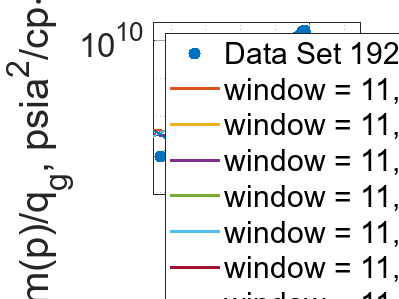

% Plot
loglog(noisy_RNP_192.t, noisy_RNP_192.RNP, ".", "MarkerSize", 25,"Color", "#0072BD", "DisplayName", "Data Set 192");
% title("Noisy RNP Data Set 192", "FontSize", 24);
set(gca, "FontSize", 20);
xlabel("t, hr", "FontSize", 24);
ylabel("\Deltam(p)/q_{g}, psia^{2}/cp\cdotd/Mscf", "FontSize", 24);
xlim([3 3000000]);
ylim([900000 30000000000]);
set(gca, "GridAlpha", 0.4);
set(gca, "MinorGridAlpha", 0.3);
grid on;
hold on;

% Degree = 1
smoothedLogRNP_192_111 = smooth(logRNP_192, 11, "sgolay", 1);
smoothedRNP_192_111 = exp(smoothedLogRNP_192_111);
residual_192_111 = (true_RNP.RNP - smoothedRNP_192_111) ./ (0.3413 .* true_RNP.RNP);
sse_192_111 = sum(residual_192_111 .^ 2);
loglog(noisy_RNP_192.t, smoothedRNP_192_111, "-", "LineWidth", 1.3, "DisplayName", "window = 11, degree = 1");
hold on;

% Degree = 2
smoothedLogRNP_192_112 = smooth(logRNP_192, 11, "sgolay", 2);
smoothedRNP_192_112 = exp(smoothedLogRNP_192_112);
residual_192_112 = (true_RNP.RNP - smoothedRNP_192_112) ./ (0.3413 .* true_RNP.RNP);
sse_192_112 = sum(residual_192_112 .^ 2);
loglog(noisy_RNP_192.t, smoothedRNP_192_112, "-", "LineWidth", 1.3, "DisplayName", "window = 11, degree = 2");
hold on;

% Degree = 3
smoothedLogRNP_192_113 = smooth(logRNP_192, 11, "sgolay", 3);
smoothedRNP_192_113 = exp(smoothedLogRNP_192_113);
residual_192_113 = (true_RNP.RNP - smoothedRNP_192_113) ./ (0.3413 .* true_RNP.RNP);
sse_192_113 = sum(residual_192_113 .^ 2);
loglog(noisy_RNP_192.t, smoothedRNP_192_113, "-", "LineWidth", 1.3, "DisplayName", "window = 11, degree = 3");
hold on;

% Degree = 4
smoothedLogRNP_192_114 = smooth(logRNP_192, 11, "sgolay", 4);
smoothedRNP_192_114 = exp(smoothedLogRNP_192_114);
residual_192_114 = (true_RNP.RNP - smoothedRNP_192_114) ./ (0.3413 .* true_RNP.RNP);
sse_192_114 = sum(residual_192_114 .^ 2);
loglog(noisy_RNP_192.t, smoothedRNP_192_114, "-", "LineWidth", 1.3, "DisplayName", "window = 11, degree = 4");
hold on;

% Degree = 5
smoothedLogRNP_192_115 = smooth(logRNP_192, 11, "sgolay", 5);
smoothedRNP_192_115 = exp(smoothedLogRNP_192_115);
residual_192_115 = (true_RNP.RNP - smoothedRNP_192_115) ./ (0.3413 .* true_RNP.RNP);
sse_192_115 = sum(residual_192_115 .^ 2);
loglog(noisy_RNP_192.t, smoothedRNP_192_115, "-", "LineWidth", 1.3, "DisplayName", "window = 11, degree = 5");
hold on;

% Degree = 6
smoothedLogRNP_192_116 = smooth(logRNP_192, 11, "sgolay", 6);
smoothedRNP_192_116 = exp(smoothedLogRNP_192_116);
residual_192_116 = (true_RNP.RNP - smoothedRNP_192_116) ./ (0.3413 .* true_RNP.RNP);
sse_192_116 = sum(residual_192_116 .^ 2);
loglog(noisy_RNP_192.t, smoothedRNP_192_116, "-", "LineWidth", 1.3, "DisplayName", "window = 11, degree = 6");
hold on;

% Degree = 7
smoothedLogRNP_192_117 = smooth(logRNP_192, 11, "sgolay", 7);
smoothedRNP_192_117 = exp(smoothedLogRNP_192_117);
residual_192_117 = (true_RNP.RNP - smoothedRNP_192_117) ./ (0.3413 .* true_RNP.RNP);
sse_192_117 = sum(residual_192_117 .^ 2);
loglog(noisy_RNP_192.t, smoothedRNP_192_117, "-", "LineWidth", 1.3, "DisplayName", "window = 11, degree = 7");
legend("Location", "northwest");
hold off;